# Thrust Vectoring M1

## Pan Mechanism

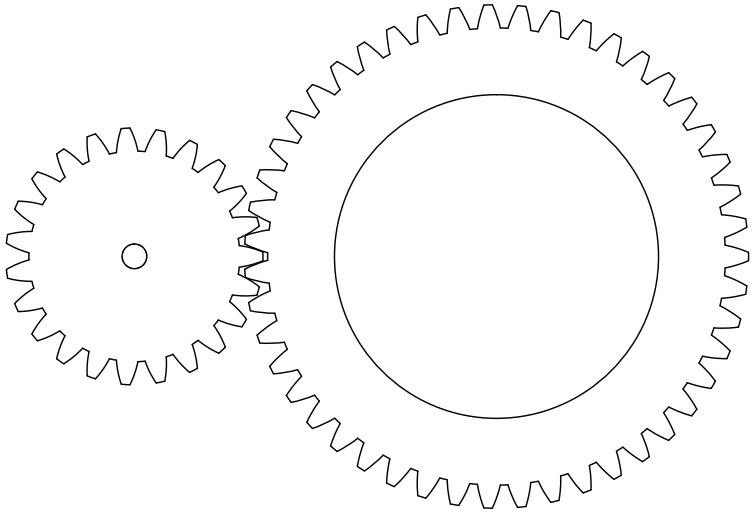

clc; clear all; close all; 

% Define Parameters

Module = 5;
N1_teeth = 20;
N2_teeth = 10;
R_depth = 15;

R1 = Module * N1_teeth;
R2 = Module * N2_teeth;
D_center = R1 + R2;
Gear_Ratio = N1_teeth / N2_teeth;
theta = (0:0.001:1)*2*pi;

% Gear radius Function (From GPT)

gear_radius = @(R_base, N) R_base - R_depth/2 + R_depth * abs(sin(N * theta));


### Gear 1

r1 = gear_radius(R1, N1_teeth);

x1_center = 0;
y1_center = 0;


### Gear 2

r2 = gear_radius(R2, N2_teeth);

x2_center = -D_center; 
y2_center = 0;


### Animation

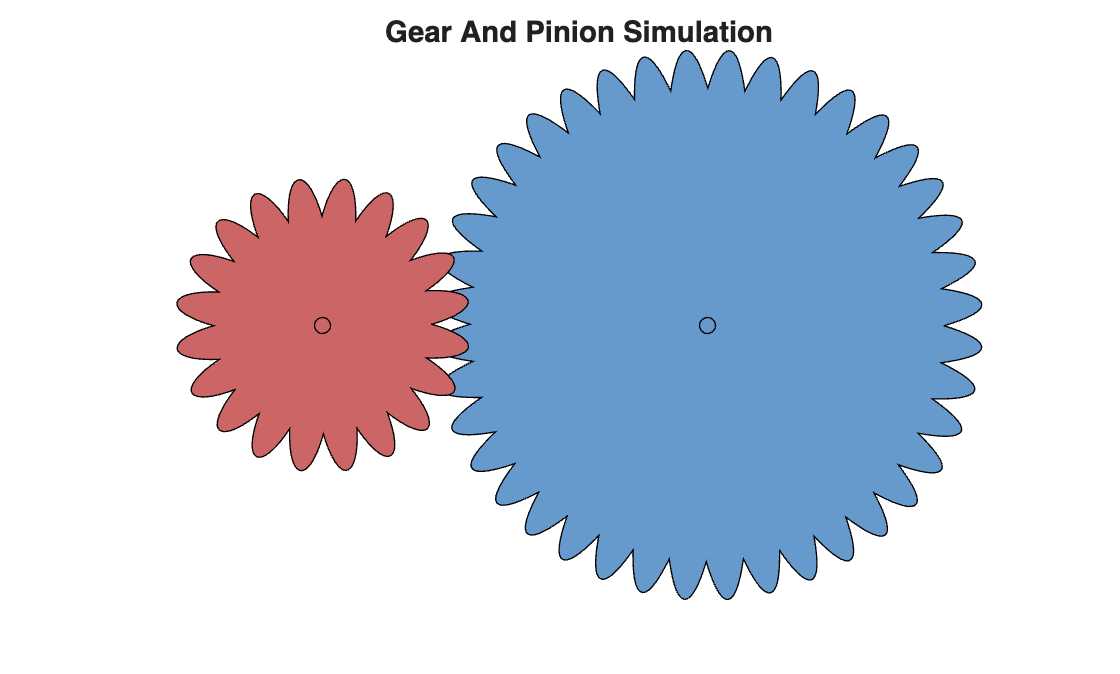

rotation_step = 0.04;

for phi_1 = 0:rotation_step:(2*pi)
    phi_2 = -phi_1 * Gear_Ratio;
    x1 = r1 .* cos(theta + phi_1) + x1_center;
    y1 = r1 .* sin(theta + phi_1) + y1_center;
    x2 = r2 .* cos(theta + phi_2) + x2_center;
    y2 = r2 .* sin(theta + phi_2) + y2_center;

    clf;
    
    hold on;
    fill(x1, y1, [0.4 0.6 0.8], 'edgecolor', 'k');
    fill(x2, y2, [0.8 0.4 0.4], 'edgecolor', 'k');

    plot(x1_center, y1_center, "ok");
    plot(x2_center,y2_center, "ok");
    
    hold off;

    axis equal;
    axis off;
    title("Gear And Pinion Simulation")
    drawnow;
end

## Tilt Mechanism

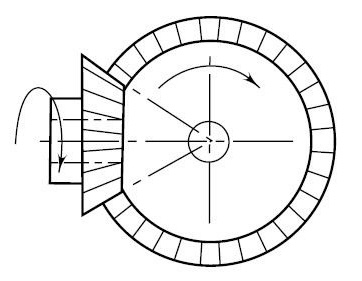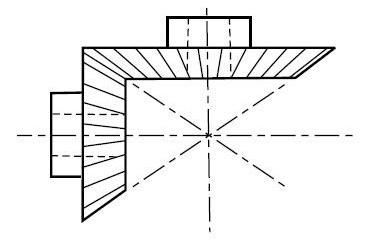

clc; clear all; close all;

% Define Parameters

module = 1.5;
N1_teeth = 40;
N2_teeth = 40;
R_depth = 15;
R_center = 10;

shaft_angle = 90;
Gear_Ratio = N1_teeth / N2_teeth;

% Calculat of Geometry (From GPT)
delta_1 = atand(N1_teeth / N2_teeth);
delta_2 = atand(N2_teeth / N1_teeth);

R1 = R_depth * sind(delta_1);
R2 = R_depth * sind(delta_2);


### Gear 1

x1 = [0, R_depth, R_depth, 0];
y1 = [0, R1, -R1, 0];
fill(x1, y1, [0.4 0.6 0.8])
hold on
plot([0 R_depth + 2], [0 0], "-k", "LineWidth", 2)

title("2D Section Veiw Of Bevel Gear")


### Gear 2

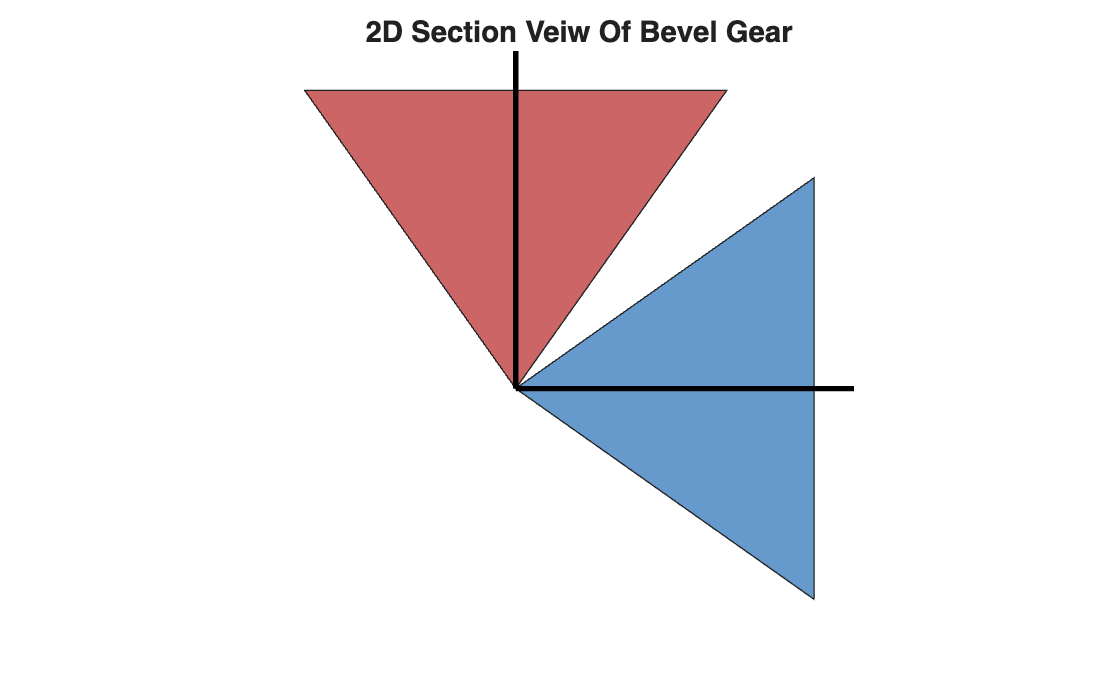

x2 = [0, R2, -R2, 0];
y2 = [0, R_depth, R_depth, 0];
fill(x2, y2, [0.8 0.4 0.4])
plot([0 0], [0 R_depth + 2], "-k", "LineWidth", 2)
axis equal
axis off

### Animation

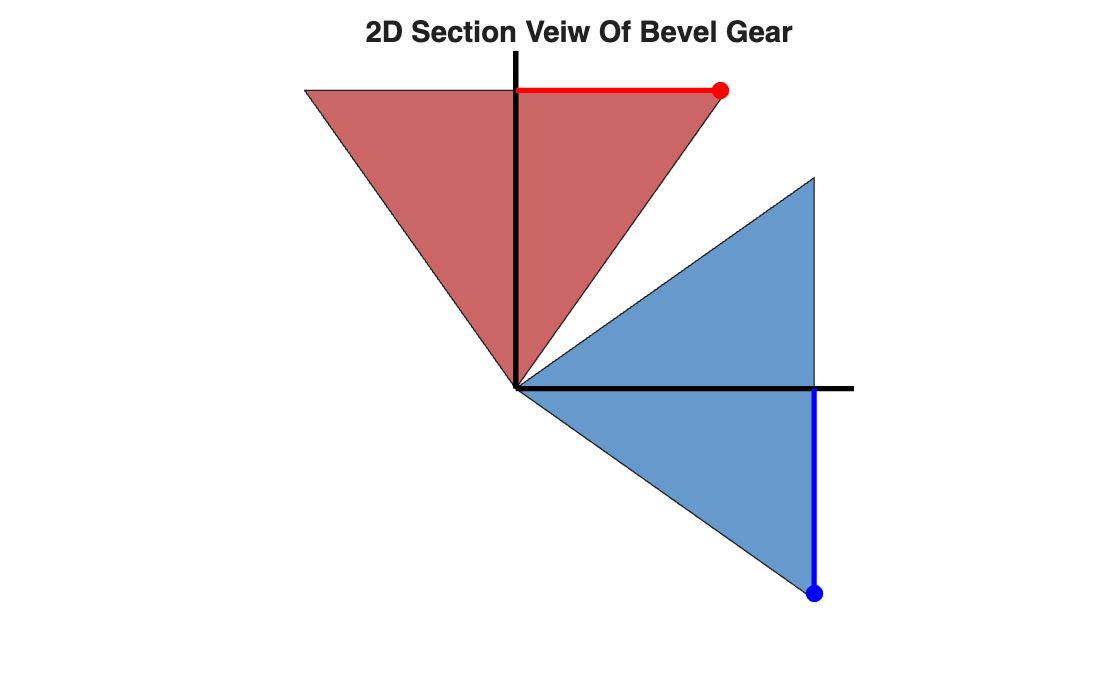

% Axis for Gear 1
base_1 = plot([R_depth R_depth], [0, 0], 'b-', 'LineWidth', 2);
tip_1 = plot(R_depth, 0, 'bo', 'MarkerFaceColor', 'b');

% Axis for Gear 2
base_2 = plot([0, 0], [R_depth, R_depth], 'r-', 'LineWidth', 2);
tip_2 = plot(0, R_depth, 'ro', 'MarkerFaceColor', 'r');

axis off

% Animation (From GPT)

angle_1 = 0;
step = 0.05;
loop = 1;

while loop < 100
    angle_1 = angle_1 + step;
    angle_2 = -angle_1 *(N1_teeth /N2_teeth);

    Rotate_1 = R1 * sin(angle_1);
    Rotate_2 = R2 * sin(angle_2);
    
    set(base_1, 'YData', [0,Rotate_1]);
    set(tip_1, 'YData', Rotate_1);
    set(base_2, 'XData', [0, Rotate_2]);
    set(tip_2, 'XData', Rotate_2);
    
    % Pause and refresh the plot
    drawnow;

    loop = loop +1;
end

hold off

## Tilt Arm Symbolic Math

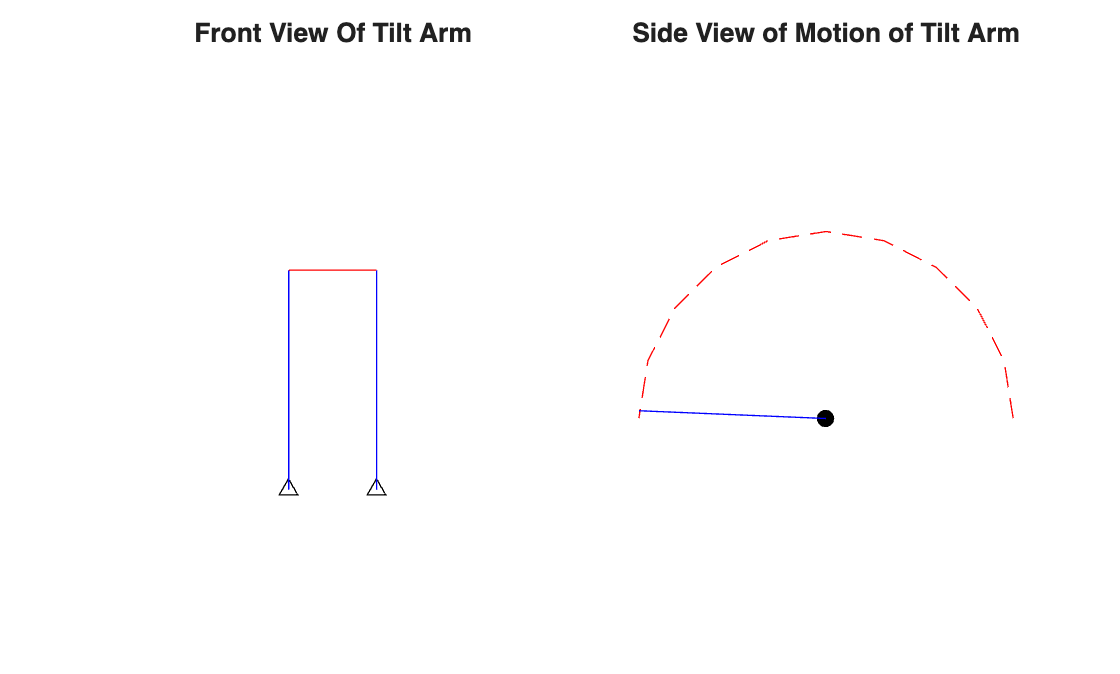

% Define Parameters
L1 = 20;
L2 = 20;
L3 = 8;
theta = sym("theta");

% Ground
O1x = 0; O1y = 0;
O2x = L3; O2y = 0;

% Plot The sketch
subplot(1, 2, 1);
plot(O1x, O1y, "^k")
hold on
plot(O2x ,O2y, "^k")
plot([0 0], [0 L1], "b")
plot([L3 L3], [0 L2], "b")
plot([0 L3], [L1 L2], "r")
xlim([-5 13])
ylim([-10 40])
hold off
title("Front View Of Tilt Arm")
axis equal
axis off

% Plot the Animation
subplot(1, 2, 2);
theta_plot = (0:0.1:1)*pi;

link_arm = @(t) plot([0 L1*cos(t)], [0 L2*sin(t)], "b");

plot(0, 0, 'ko', 'MarkerFaceColor', 'k');
hold on
title("Side View of Motion of Tilt Arm")
plot(0, 0, 'ko', 'MarkerFaceColor', 'k');
plot(L1*cos(theta_plot), L1*sin(theta_plot), 'r--')
ylim([-10 20])

axis equal
axis off

fanimator(link_arm, "AnimationRange", [0 pi])
hold off


playAnimation

## Graphical Analysis

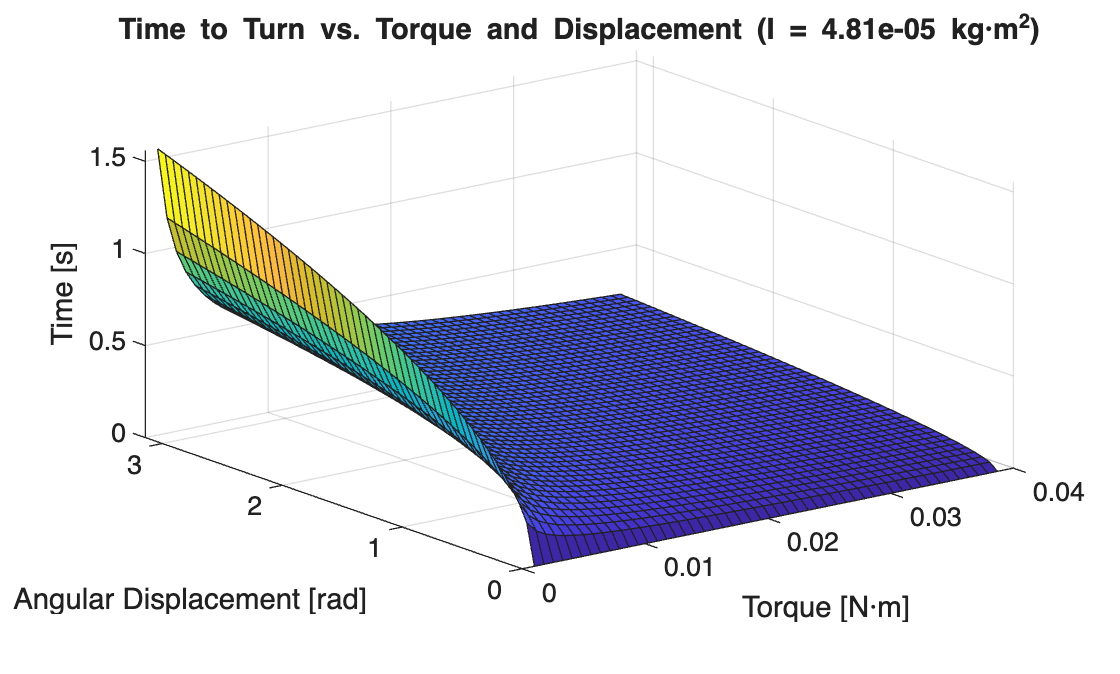

clc; clear all; close all;

% Pan Section Velocity and DC-motor Torque

% Pan Graph of Torque and Motion


I = 4.81*(10^-5);


torque = linspace(0.001,0.0387,50);
angle = linspace(0,pi(),50);


[T,theta] = meshgrid(torque,angle);


% Derived time equation "bang-bang" configuration

time = 4.*sqrt((I.*theta)./T);


surf(T,theta,time)


title(['Time to Turn vs. Torque and Displacement (I = ' num2str(I) ' kg·m^2)']);
xlabel('Torque [N·m]');
ylabel('Angular Displacement [rad]');
zlabel('Time [s]');

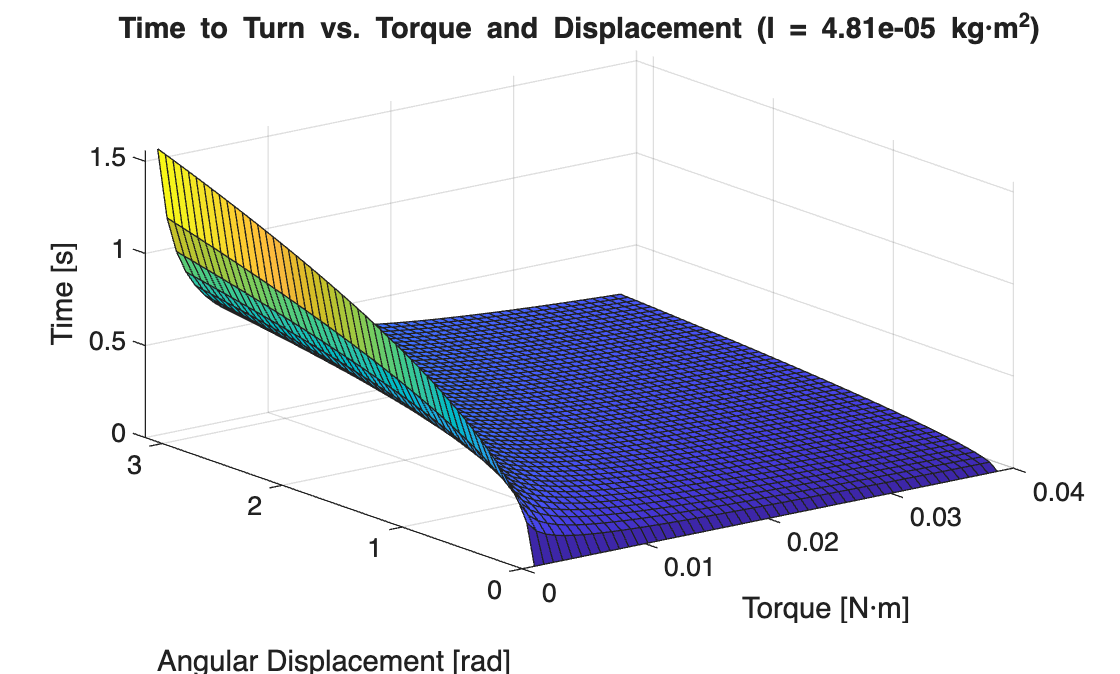



% Tilt Section Velocity and DC-motor Torque

% Tilt Graph of Torque and Motion


I = 4.81*(10^-5);


torque = linspace(0.001,0.0387,50);
angle = linspace(0,pi(),50);


[T,theta] = meshgrid(torque,angle);


% Derived time equation "bang-bang" configuration

time = 4.*sqrt((I.*theta)./T);


surf(T,theta,time)


title(['Time to Turn vs. Torque and Displacement (I = ' num2str(I) ' kg·m^2)']);
xlabel('Torque [N·m]');
ylabel('Angular Displacement [rad]');
zlabel('Time [s]');

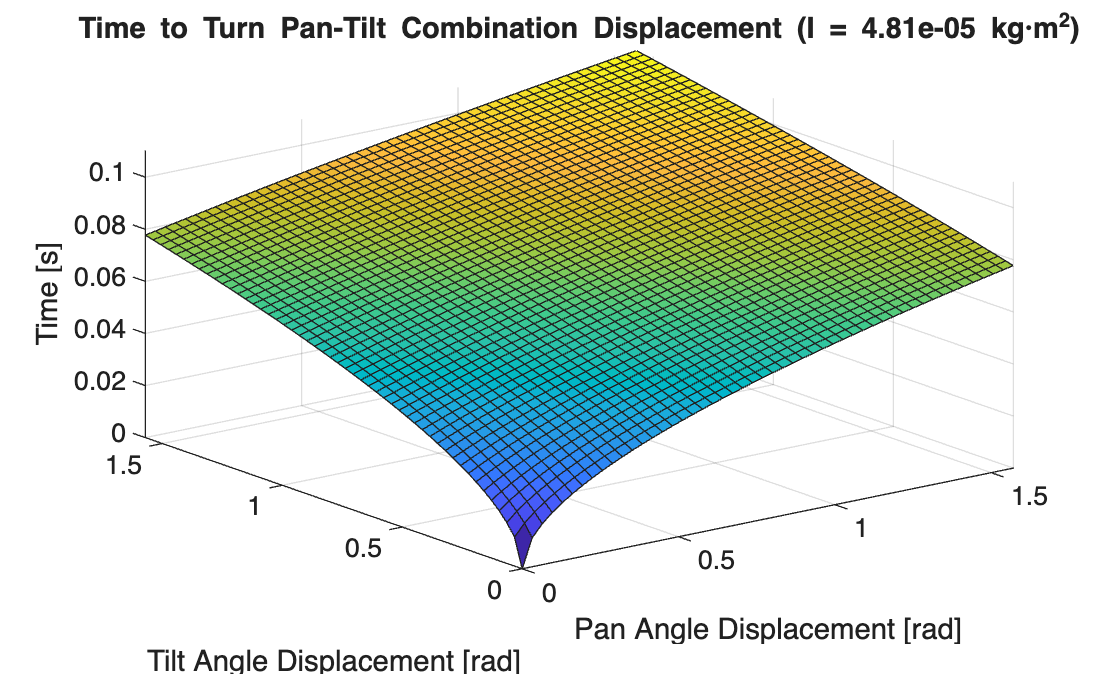



% Pan - Tilt Combination Graph


I = 4.81*(10^-5);


torqueA = 0.2;
torqueB = 0.2;


pan_angle = linspace(0,pi()/2,50);
tilt_angle = linspace(0,pi()/2,50);


[pan_angle,tilt_angle] = meshgrid(pan_angle,tilt_angle);


% Derived torque input
torque_pan = torqueA;
torque_tilt = torqueB - torqueA;


% Finding the max t for Pan and Tilt
tA = 4*sqrt((pan_angle.*I)/(torqueA));
tB = 4*sqrt(((I.*tilt_angle)+(I.*pan_angle))/(torqueB));


% Finding the max time taken for the process
time = max(tA,tB);


surf(pan_angle,tilt_angle,time)


title(['Time to Turn Pan-Tilt Combination Displacement (I = ' num2str(I) ' kg·m^2)']);
xlabel('Pan Angle Displacement [rad]');
ylabel('Tilt Angle Displacement [rad]');
zlabel('Time [s]');